% 0.Initialising Variables
file = "example_1"

file = "example_1"

save_folder = "results/" + file

save_folder = "results/example_1"

if  ~exist(save_folder, 'dir')
    mkdir(save_folder);
end
save_name = save_folder + "/" +file + "_"

save_name = "results/example_1/example_1_"

load(file + ".mat")
A = adjacency_matrix

A =      0     1     0     1     0     0     0
     1     0     1     1     0     0     0
     1     1     0     1     0     0     0
     1     0     1     0     0     0     0
     1     0     0     0     0     0     0
     0     1     0     0     0     0     1
     0     0     0     0     0     1     0


[A, remaining_nodes] = remove_unconnected_nodes(A);
node_labels = 1:1:numel(A);

n = size(A, 1); % dimension
alpha = 0.85

alpha = 0.8500

v = ones(n, 1)/n;
iterations = 50;

% 1.Column normalisation
r = sum(A, 2); % in degree
c = sum(A, 1); % out degree
e = ones(n, 1);
H = A;
for i = 1:numel(c)
    if c(i)~=0
        H(:,i) = A(:,i)./c(i);
    else
        H(:,i) = A(:,i);
    end
end

% 1.1 Displaying stuff
A

A =      0     1     0     1     0     0     0
     1     0     1     1     0     0     0
     1     1     0     1     0     0     0
     1     0     1     0     0     0     0
     1     0     0     0     0     0     0
     0     1     0     0     0     0     1
     0     0     0     0     0     1     0


in_degree = r

in_degree =      2
     3
     3
     2
     1
     2
     1


out_degree = c

out_degree =      4     3     2     3     0     1     1


H

H =          0    0.3333         0    0.3333         0         0         0
    0.2500         0    0.5000    0.3333         0         0         0
    0.2500    0.3333         0    0.3333         0         0         0
    0.2500         0    0.5000         0         0         0         0
    0.2500         0         0         0         0         0         0
         0    0.3333         0         0         0         0    1.0000
         0         0         0         0         0    1.0000         0


% 2.Stochastic Adjustment
a = ones(size(H, 1), 1);
for j = 1:size(H, 2)
    for i = 1:size(H, 1)
        if H(i, j) ~= 0
            a(j) = 0; % computing dangling node vector
            break;
        end
    end
end
S = H + (e * a')/n;

% 2.1 displaying stuff
a

a =      0
     0
     0
     0
     1
     0
     0


stochastic_adjustment = e*a'/n

stochastic_adjustment =          0         0         0         0    0.1429         0         0
         0         0         0         0    0.1429         0         0
         0         0         0         0    0.1429         0         0
         0         0         0         0    0.1429         0         0
         0         0         0         0    0.1429         0         0
         0         0         0         0    0.1429         0         0
         0         0         0         0    0.1429         0         0


S

S =          0    0.3333         0    0.3333    0.1429         0         0
    0.2500         0    0.5000    0.3333    0.1429         0         0
    0.2500    0.3333         0    0.3333    0.1429         0         0
    0.2500         0    0.5000         0    0.1429         0         0
    0.2500         0         0         0    0.1429         0         0
         0    0.3333         0         0    0.1429         0    1.0000
         0         0         0         0    0.1429    1.0000         0


% 3.Transition Probability
G = alpha*S + (1-alpha)*v*e';

% 3.1 Displaying stuff
teleportation_matrix = v*e'

teleportation_matrix =     0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429
    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429
    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429
    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429
    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429
    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429
    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429


G

G =     0.0214    0.3048    0.0214    0.3048    0.1429    0.0214    0.0214
    0.2339    0.0214    0.4464    0.3048    0.1429    0.0214    0.0214
    0.2339    0.3048    0.0214    0.3048    0.1429    0.0214    0.0214
    0.2339    0.0214    0.4464    0.0214    0.1429    0.0214    0.0214
    0.2339    0.0214    0.0214    0.0214    0.1429    0.0214    0.0214
    0.0214    0.3048    0.0214    0.0214    0.1429    0.0214    0.8714
    0.0214    0.0214    0.0214    0.0214    0.1429    0.8714    0.0214


% 4.Power method
p = ones(n, 1);
p = p/sum(p);
kth_iteration = cell(1,iterations + 1);
kth_iteration{1} = p;
for k = 1:iterations
    p = G*p;
    kth_iteration{k+1} = p;
end

% 4.1 displaying Stuff
our_p = p

our_p =     0.0836
    0.1125
    0.1013
    0.0877
    0.0446
    0.2938
    0.2766



[V,D] = eig(G);                      % find the eigenvalues and the eigenvectors
[~,ind] = min(abs(diag(D)-1));       % find the index of the eigenvalue 1 (not exactly because of numerical error)
eigenvector_p = V(:,1)/sum(V(:,1))  % normalised eigenvector as the PageRank vector

eigenvector_p =     0.0836
    0.1125
    0.1013
    0.0877
    0.0446
    0.2938
    0.2766



centrality_p = centrality(digraph(transpose(A)),'pagerank','FollowProbability',alpha)

centrality_p =     0.0836
    0.1125
    0.1013
    0.0877
    0.0446
    0.2938
    0.2766


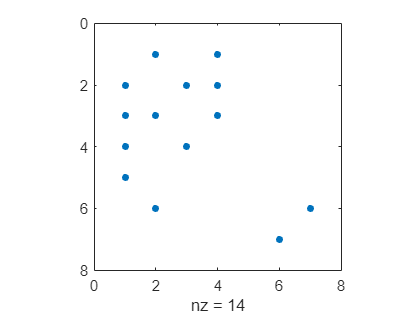

% 5 Pretty pictures

% Displaying Adjacency matrix
figure;
spy(A);

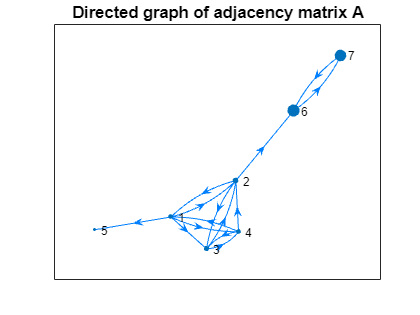

spy_plot = gcf;

% Displaying graph
graph_A = digraph(A');
gp = plot(graph_A, 'Layout', 'force');
title("Directed graph of adjacency matrix A");
gp.MarkerSize = 7*p/max(p) + 0.1;
gp.EdgeColor = [0,0.5,1];
gp.EdgeAlpha = 1;

row = dataTipTextRow('label: ',node_labels);
gp.DataTipTemplate.DataTipRows(end+1) = row;
graph_plot = gp;

% Displaying ranks of nodes
[ranks, indicies] = sort(p, 'descend');
rank_node_labels = node_labels(indicies);
amount = min(100, size(A));
top_page_ranks = ranks(1:amount);
top_node_labels = rank_node_labels(1:amount)';
rank_table = table(top_page_ranks, top_node_labels)

rank_table = 7×2 table
    top_page_ranks    top_node_labels
    ______________    _______________

        0.29381              6       
        0.27659              7       
        0.11249              2       
        0.10131              3       
       0.087654              4       
       0.083551              1       
       0.044599              5       


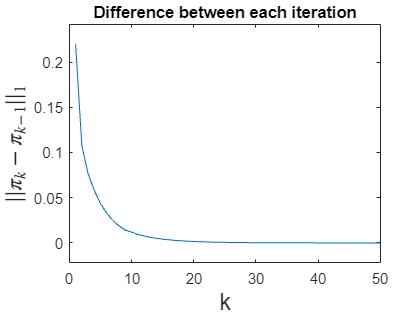


% Plotting difference between each iteration
figure;
differences = [];
for i = 1:numel(kth_iteration) - 1
    diff = kth_iteration{i+1} - kth_iteration{i};
    differences(i) = norm(diff, 1);
end
diff_1_plot = plot(1:iterations, differences);
title("Difference between each iteration")
ylabel("$$||\pi_{k} - \pi_{k-1}||_1$$", 'Interpreter', 'latex', 'FontSize', 15);
xlabel("k", 'FontSize', 15);
ylim([-0.1*max(differences) 1.1*max(differences)])

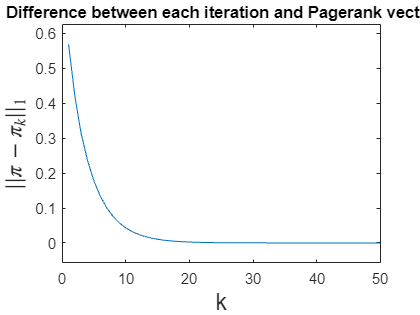


% Plotting difference to eigenvector
figure;
differences = [];
for i = 1:numel(kth_iteration) - 1
    diff = eigenvector_p - kth_iteration{i};
    differences(i) = norm(diff, 1);
end
diff_2_plot = plot(1:iterations, differences);
title("Difference between each iteration and Pagerank vector")
ylabel("$$||\pi - \pi_{k}||_1$$", 'Interpreter', 'latex', 'FontSize', 15);
xlabel("k", 'FontSize', 15);
ylim([-0.1*max(differences) 1.1*max(differences)]);

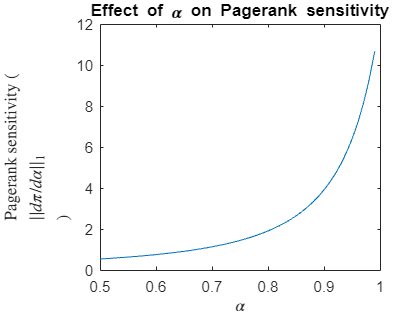


% Testing how sensitivity changes wrt alpha parameter
figure;
alpha_values = .5:.01:.99;
sensitivities = [];
v = e/n;
for i = 1:numel(alpha_values)
    sensitivity_vector = pr_alpha_sensitivity(A, alpha_values(i), v);
    sensitivities(end + 1) = norm(sensitivity_vector, 1);
end
sensitivity_plot = plot(alpha_values, sensitivities);
xlabel("$$\alpha$$", "Interpreter","latex");
ylabel("Pagerank sensitivity ($$|| d \pi / d \alpha||_1$$)", "Interpreter","latex");
title("Effect of \alpha on Pagerank sensitivity")

"exporting figures"

ans = "exporting figures"

saveas(graph_plot, save_name + "graph", "png");
saveas(diff_1_plot, save_name + "diff_1", "png");

saveas(diff_2_plot, save_name + "diff_2", "png");

saveas(spy_plot, save_name + "adjacency", "png");

saveas(sensitivity_plot, save_name + "sensitivity_plot", "png");

table2latex(rank_table, char(save_name + "table"));
save_matrix(A, save_name + "adjacency");
save_matrix(H, save_name + "column_normalised_adjacency");
save_matrix(S, save_name + "stochastic");
save_matrix(G, save_name + "google");

function [] = save_matrix(matrix, save_path)
    save_path = save_path + ".tex";
    fileID = fopen(save_path, "w");
    fprintf(fileID,"%s", latex(sym(matrix)));
    fclose(fileID);
end